## Brug af `eulsys` og `rk4system`

Eksempel: Differentialligningssystem for frit fald. Tilbagelagt faldafstand og hastighed betegnes henholdsvis $x$ og $v$ (der regnes positiv nedad).

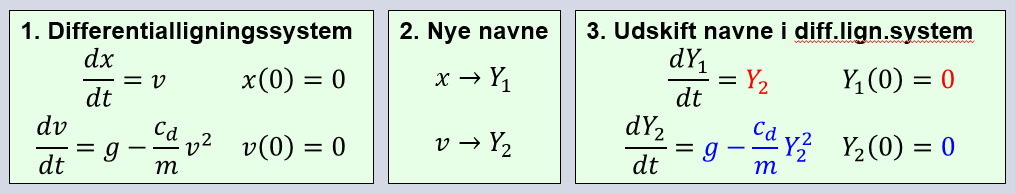

**4. Benyt resultater i **`eulsys`** og **`rk4system`

g = 9.81; m = 68.1; cd = 0.25;
dYdt = @(t,Y) [Y(2), g-cd/m*Y(2)^2]; % Definerer dYdt - udregner IKKE noget!
Y0 = [0 0];
tidsinterval = [0 12];
h = 2;

disp('================ Eulers metode =================')

================ Eulers metode =================


[t,Y] = eulsys(@dYdt,tidsinterval,Y0,h);
x = Y(:,1); v = Y(:,2);
disp(table(t,x,v))

    t       x         v   
    __    ______    ______
     0         0         0
     2         0     19.62
     4     39.24    36.414
     6    112.07    46.298
     8    204.66     50.18
    10    305.02    51.312
    12    407.65    51.601


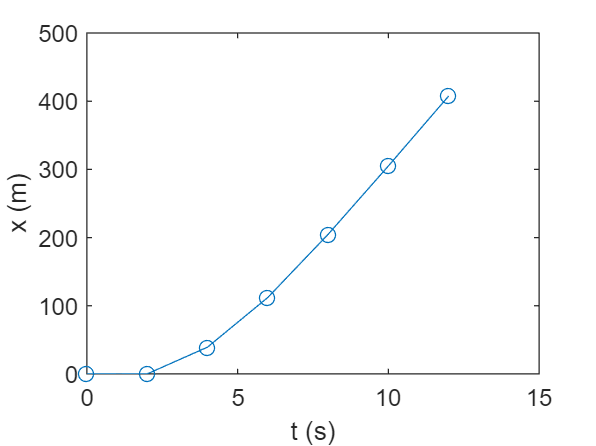

figure(1), plot(t,x,'-o'), hold on
xlabel('t (s)'), ylabel('x (m)')

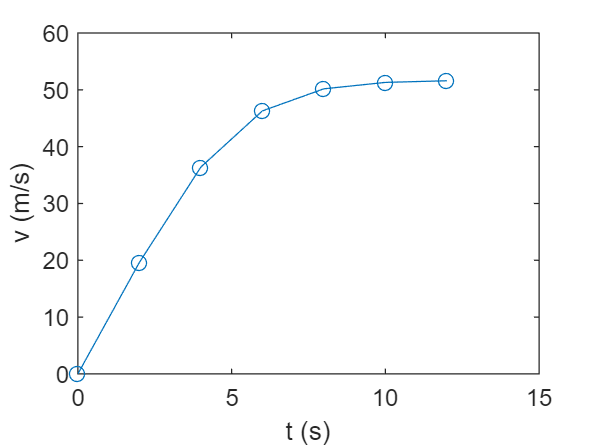

figure(2), plot(t,v,'-o'), hold on
xlabel('t (s)'), ylabel('v (m/s)')

disp('======== Fjerdeordens Runge-Kuttametode ========')

======== Fjerdeordens Runge-Kuttametode ========


[t,Y] = rk4system(dYdt,tidsinterval,Y0,h);
x = Y(:,1); v = Y(:,2);
disp(table(t,x,v))

    t       x         v   
    __    ______    ______
     0         0         0
     2    19.166    18.726
     4    71.931    33.099
     6    147.95    42.055
     8    237.51    46.934
    10    334.16    49.403
    12    434.33    50.605


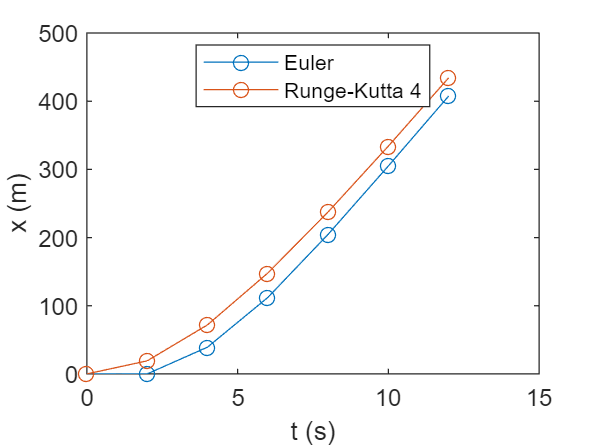

figure(1), plot(t,x,'-o'), hold off
legend('Euler','Runge-Kutta 4','Location','Best')

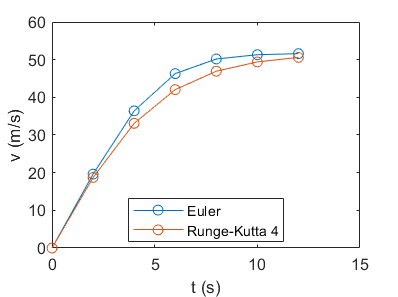

figure(2), plot(t,v,'-o'), hold off
legend('Euler','Runge-Kutta 4','Location','Best')